# Split up genotype and ovary

%% Step 1: Ensure Correct Data Types and Extract Factors
% Convert group to string format if it's categorical
aallBLAves.group = string(aallBLAves.group);

% Extract genotype (WT/TG) and hormone status (P/O)
aallBLAves.Genotype = categorical(extractBefore(aallBLAves.group, 3)); % First 2 characters
aallBLAves.HormoneStatus = categorical(extractAfter(aallBLAves.group, 2)); % Last character


%% Step 2: Two-Way ANOVA for Firing Rate
disp('ANOVA for Firing Rate');

ANOVA for Firing Rate


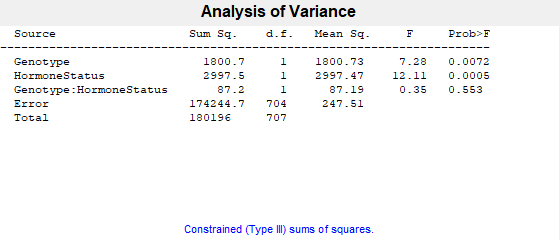

[p_FR, tbl_FR, stats_FR] = anovan(aallBLAves.spikePtime, ...
    {aallBLAves.Genotype, aallBLAves.HormoneStatus}, ...
    'model', 'interaction', ...
    'varnames', {'Genotype', 'HormoneStatus'});

disp(tbl_FR);

    {'Source'                }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'Genotype'              }    {[1.8007e+03]}    {[   1]}    {[        0]}    {[1.8007e+03]}    {[  7.2755]}    {[    0.0072]}
    {'HormoneStatus'         }    {[2.9975e+03]}    {[   1]}    {[        0]}    {[2.9975e+03]}    {[ 12.1107]}    {[5.3224e-04]}
    {'Genotype:HormoneStatus'}    {[   87.1865]}    {[   1]}    {[        0]}    {[   87.1865]}    {[  0.3523]}    {[    0.5530]}
    {'Error'                 }    {[1.7424e+05]}    {[ 704]}    {[        0]}    {[  247.5067]}    {0×0 double}    {0×0 double  }
    {'Total'                 }    {[1.8020e+05]}    {[ 707]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double  }




% Tukey Post-hoc Tests for Firing Rate
multcompare(stats_FR, 'Dimension', 1); % Genotype
multcompare(stats_FR, 'Dimension', 2); % Hormone Status
[c_FR_geno,~,~,groupNames_FR_geno] = multcompare(stats_FR, 'Dimension', 1); % Genotype
[c_FR_hormone,~,~,groupNames_FR_hormone] = multcompare(stats_FR, 'Dimension', 2); % Hormone Status


%% Step 3: Two-Way ANOVA for ISI
disp('ANOVA for ISI');
[p_ISI, tbl_ISI, stats_ISI] = anovan(allBLAves.ISI, ...
    {allBLAves.Genotype, allBLAves.HormoneStatus}, ...
    'model', 'interaction', ...
    'varnames', {'Genotype', 'HormoneStatus'});
disp(tbl_ISI);

% Tukey Post-hoc Tests for ISI
multcompare(stats_ISI, 'Dimension', 1); % Genotype
multcompare(stats_ISI, 'Dimension', 2); % Hormone Status
[c_ISI_geno,~,~,groupNames_ISI_geno] = multcompare(stats_ISI, 'Dimension', 1); % Genotype
[c_ISI_hormone,~,~,groupNames_ISI_hormone] = multcompare(stats_ISI, 'Dimension', 2); % Hormone Status



%% Step 4: Bar Plots for Both Measures (Firing Rate & ISI)
% Ensure 'group' is categorical and enforce specific order
allBLAves.group = categorical(allBLAves.group, {'WTP', 'TGP', 'WTO', 'TGO'}, 'Ordinal', true);

% Define colors for the groups
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

% Get unique group names (in the specified order)
groupNames = categories(allBLAves.group);
numGroups = numel(groupNames);

% Preallocate arrays for means and standard errors
means_FR = zeros(1, numGroups);
stdErrs_FR = zeros(1, numGroups);
means_ISI = zeros(1, numGroups);
stdErrs_ISI = zeros(1, numGroups);

% Compute mean and standard error for each group (Firing Rate & ISI)
for i = 1:numGroups
    groupData_FR = allBLAves.FiringRate(allBLAves.group == groupNames{i});
    means_FR(i) = mean(groupData_FR);
    stdErrs_FR(i) = std(groupData_FR) / sqrt(numel(groupData_FR)); % Standard error

    groupData_ISI = allBLAves.ISI(allBLAves.group == groupNames{i});
    means_ISI(i) = mean(groupData_ISI);
    stdErrs_ISI(i) = std(groupData_ISI) / sqrt(numel(groupData_ISI)); % Standard error
end

% Create figure for Firing Rate
figure;
barHandle_FR = bar(means_FR, 'FaceColor', 'flat'); 
hold on;
for i = 1:numGroups
    barHandle_FR.CData(i, :) = groupColors(i, :);
end
errorbar(1:numGroups, means_FR, stdErrs_FR, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
hold off;
xticklabels(groupNames);
xlabel('Group');
ylabel('Mean Firing Rate (Hz)');
title('Firing Rate Across Groups');
set(gca, 'FontSize', 12, 'Box', 'off');
grid on;

% Create figure for ISI
figure;
barHandle_ISI = bar(means_ISI, 'FaceColor', 'flat'); 
hold on;
for i = 1:numGroups
    barHandle_ISI.CData(i, :) = groupColors(i, :);
end
errorbar(1:numGroups, means_ISI, stdErrs_ISI, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
hold off;
xticklabels(groupNames);
xlabel('Group');
ylabel('Mean ISI (ms)');
title('ISI Across Groups');
set(gca, 'FontSize', 12, 'Box', 'off');
grid on;


Cumulkative distribution

%% Step 1: Define Groups and Colors
groups = {'WTP', 'TGP', 'WTO', 'TGO'};
group_colors = [1 0.75 0.8;  % WTP - Light pink
                0.7 0.5 0.7;  % TGP - Purple
                0.85 0.3 0.5; % WTO - Reddish Pink
                0.5 0.1 0.4]; % TGO - Dark Purple

%% Step 2: Compute CDF for Firing Rate
fprintf('\nProcessing CDF for Firing Rate\n');

% Initialize storage for fitted parameters
params_FR = cell(1, length(groups));

% Define x-axis range for CDF
x_FR = linspace(0, max(allBLAves.FiringRate), 100);

% Create figure for Firing Rate CDF
figure; hold on;
for g = 1:length(groups)
    % Extract and clean data
    groupData_FR = allBLAves.FiringRate(allBLAves.group == groups{g});
    groupData_FR = groupData_FR(~isnan(groupData_FR) & ~isinf(groupData_FR));
    
    % Fit gamma distribution if data is available
    if ~isempty(groupData_FR)
        params_FR{g} = gamfit(groupData_FR);
        FR_cdf = gamcdf(x_FR, params_FR{g}(1), params_FR{g}(2));
        
        % Plot CDF
        plot(x_FR, FR_cdf, 'LineWidth', 3, 'Color', group_colors(g, :), ...
             'DisplayName', groups{g});
    end
end

% Formatting
xlabel('Firing Rate (Hz)');
ylabel('Cumulative Probability');
title('CDF of Firing Rate');
set(gca, 'FontSize', 16, 'FontName', 'Arial');
legend('show');
grid on;
hold off;

%% Step 3: Compute CDF for ISI
fprintf('\nProcessing CDF for ISI\n');

% Initialize storage for fitted parameters
params_ISI = cell(1, length(groups));

% Define x-axis range for CDF
x_ISI = linspace(0, max(allBLAves.ISI), 100);

% Create figure for ISI CDF
figure; hold on;
for g = 1:length(groups)
    % Extract and clean data
    groupData_ISI = allBLAves.ISI(allBLAves.group == groups{g});
    groupData_ISI = groupData_ISI(~isnan(groupData_ISI) & ~isinf(groupData_ISI));
    
    % Fit gamma distribution if data is available
    if ~isempty(groupData_ISI)
        params_ISI{g} = gamfit(groupData_ISI);
        ISI_cdf = gamcdf(x_ISI, params_ISI{g}(1), params_ISI{g}(2));
        
        % Plot CDF
        plot(x_ISI, ISI_cdf, 'LineWidth', 3, 'Color', group_colors(g, :), ...
             'DisplayName', groups{g});
    end
end

% Formatting
xlabel('ISI (s)');
ylabel('Cumulative Probability');
title('CDF of ISI');
set(gca, 'FontSize', 16, 'FontName', 'Arial');
legend('show');
grid on;
hold off;


FIguring out correlartion

% Compute correlation between FR and ISI
[r, p] = corr(allBLAves.FiringRate, allBLAves.ISI, 'Type', 'Spearman'); % Non-parametric
fprintf('Spearman correlation between Firing Rate and ISI: r = %.3f, p = %.3f\n', r, p);
figure;
scatter(allBLAves.ISI, allBLAves.FiringRate, 50, 'b', 'filled');
xlabel('ISI (s)');
ylabel('Firing Rate (Hz)');
title('ISI vs. Firing Rate');
set(gca, 'FontSize', 14);
grid on;

# Epoch By Group Averages

% Define groups and epochs
groups = {'WTP', 'TGP', 'WTO', 'TGO'}; % Expected group order
epochs = {'BLFR', 'FSFR', 'restFR'}; % Epoch labels

% Define group colors
groupColors = [1 0.75 0.8;  % WTP (light pink)
               0.7 0.5 0.7;  % TGP (purple)
               0.85 0.3 0.5; % WTO (reddish pink)
               0.5 0.1 0.4]; % TGO (dark purple)]

% Initialize matrices for averages and SEMs
numEpochs = length(epochs);
groupAverages = zeros(length(groups), numEpochs);
groupSEMs = zeros(length(groups), numEpochs);

% Store dataset references for each epoch
epochTables = {allBLAves, allFsAves, allRestAves};

% Calculate the mean and SEM of firing rate for each group in each epoch
for g = 1:length(groups)
    for e = 1:numEpochs
        % Extract firing rate values for the current group from the corresponding table
        groupData = epochTables{e}.NewFR(strcmp(epochTables{e}.group, groups{g}));

        % Compute mean and SEM, omitting NaN values
        groupAverages(g, e) = mean(groupData, 'omitnan');
        groupSEMs(g, e) = std(groupData, 'omitnan') / sqrt(sum(~isnan(groupData)));
    end
end

% Display computed averages and SEMs
disp('Group Averages:');
disp(array2table(groupAverages, 'VariableNames', epochs, 'RowNames', groups));

disp('Group SEMs:');
disp(array2table(groupSEMs, 'VariableNames', epochs, 'RowNames', groups));

% Create scatter plot with error bars
figure;
hold on;

for g = 1:length(groups)
    % Scatter plot for each group's average firing rate per epoch
    scatter(1:numEpochs, groupAverages(g, :), 100, groupColors(g, :), 'filled', ...
        'DisplayName', groups{g});
    
    % Connect scatter points with lines (hidden in legend)
    lineHandle = plot(1:numEpochs, groupAverages(g, :), '-o', 'LineWidth', 1.5, ...
        'Color', groupColors(g, :));
    set(get(get(lineHandle, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
    
    % Add error bars for SEM
    e = errorbar(1:numEpochs, groupAverages(g, :), groupSEMs(g, :), 'LineStyle', 'none', ...
        'Color', groupColors(g, :), 'LineWidth', 1.2);
    set(get(get(e, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
end

% Customize plot appearance
xlim([0.5, numEpochs + 0.5]);
xticks(1:numEpochs);
xticklabels(epochs);
ylabel('Average Firing Rate (Hz)', 'FontSize', 14);
xlabel('Epoch', 'FontSize', 14);
legend('show', 'Location', 'best'); % Display legend
set(gca, 'FontSize', 12);

% Add grid and format colors
grid on;
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
set(gcf, 'Color', 'w');
hold off;


%%%%%Bar graph Old firing rate
%% Step 1: Ensure Correct Data Types and Extract Factors
% Convert group to string format if it's categorical
allBLAves.group = string(allBLAves.group);

% Extract genotype (WT/TG) and hormone status (P/O)
allBLAves.Genotype = categorical(extractBefore(allBLAves.group, 3)); % First 2 characters
allBLAves.HormoneStatus = categorical(extractAfter(allBLAves.group, 2)); % Last character

%% Step 2: Two-Way ANOVA for Firing Rate
disp('ANOVA for Firing Rate');
[p_FR, tbl_FR, stats_FR] = anovan(allBLAves.FiringRate, ...
    {allBLAves.Genotype, allBLAves.HormoneStatus}, ...
    'model', 'interaction', ...
    'varnames', {'Genotype', 'HormoneStatus'});
disp(tbl_FR);

% Tukey Post-hoc Tests for Firing Rate
multcompare(stats_FR, 'Dimension', 1); % Genotype
multcompare(stats_FR, 'Dimension', 2); % Hormone Status
[c_FR_geno,~,~,groupNames_FR_geno] = multcompare(stats_FR, 'Dimension', 1); % Genotype
[c_FR_hormone,~,~,groupNames_FR_hormone] = multcompare(stats_FR, 'Dimension', 2); % Hormone Status

%% Step 3: Two-Way ANOVA for ISI
disp('ANOVA for ISI');
[p_ISI, tbl_ISI, stats_ISI] = anovan(allBLAves.ISI, ...
    {allBLAves.Genotype, allBLAves.HormoneStatus}, ...
    'model', 'interaction', ...
    'varnames', {'Genotype', 'HormoneStatus'});
disp(tbl_ISI);

% Tukey Post-hoc Tests for ISI
multcompare(stats_ISI, 'Dimension', 1); % Genotype
multcompare(stats_ISI, 'Dimension', 2); % Hormone Status
[c_ISI_geno,~,~,groupNames_ISI_geno] = multcompare(stats_ISI, 'Dimension', 1); % Genotype
[c_ISI_hormone,~,~,groupNames_ISI_hormone] = multcompare(stats_ISI, 'Dimension', 2); % Hormone Status

%% Step 4: Bar Plots for Both Measures (Firing Rate & ISI)
% Ensure 'group' is categorical and enforce specific order
allBLAves.group = categorical(allBLAves.group, {'WTP', 'TGP', 'WTO', 'TGO'}, 'Ordinal', true);

% Define colors for the groups
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

% Get unique group names (in the specified order)
groupNames = categories(allBLAves.group);
numGroups = numel(groupNames);

% Preallocate arrays for means and standard errors
means_FR = zeros(1, numGroups);
stdErrs_FR = zeros(1, numGroups);
means_ISI = zeros(1, numGroups);
stdErrs_ISI = zeros(1, numGroups);

% Compute mean and standard error for each group (Firing Rate & ISI)
for i = 1:numGroups
    groupData_FR = allBLAves.FiringRate(allBLAves.group == groupNames{i});
    means_FR(i) = mean(groupData_FR);
    stdErrs_FR(i) = std(groupData_FR) / sqrt(numel(groupData_FR)); % Standard error

    groupData_ISI = allBLAves.ISI(allBLAves.group == groupNames{i});
    means_ISI(i) = mean(groupData_ISI);
    stdErrs_ISI(i) = std(groupData_ISI) / sqrt(numel(groupData_ISI)); % Standard error
end

% Create figure for Firing Rate
figure;
barHandle_FR = bar(means_FR, 'FaceColor', 'flat'); 
hold on;
for i = 1:numGroups
    barHandle_FR.CData(i, :) = groupColors(i, :);
end
errorbar(1:numGroups, means_FR, stdErrs_FR, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
hold off;
xticklabels(groupNames);
xlabel('Group');
ylabel('Mean Firing Rate (Hz)');
title('1/ISI Rate Across Groups');
set(gca, 'FontSize', 12, 'Box', 'off');
grid on;

% Create figure for ISI
figure;
barHandle_ISI = bar(means_ISI, 'FaceColor', 'flat'); 
hold on;
for i = 1:numGroups
    barHandle_ISI.CData(i, :) = groupColors(i, :);
end
errorbar(1:numGroups, means_ISI, stdErrs_ISI, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
hold off;
xticklabels(groupNames);
xlabel('Group');
ylabel('Mean ISI (ms)');
title('ISI Across Groups');
set(gca, 'FontSize', 12, 'Box', 'off');
grid on;


%%%%%Bar graph new FR
%% Step 1: Ensure Correct Data Types and Extract Factors
% Convert group to string format if it's categorical
allBLAves.group = string(allBLAves.group);

% Extract genotype (WT/TG) and hormone status (P/O)
allBLAves.Genotype = categorical(extractBefore(allBLAves.group, 3)); % First 2 characters
allBLAves.HormoneStatus = categorical(extractAfter(allBLAves.group, 2)); % Last character

%% Step 2: Two-Way ANOVA for Firing Rate
disp('ANOVA for Firing Rate');
[p_FR, tbl_FR, stats_FR] = anovan(allBLAves.NewFR, ...
    {allBLAves.Genotype, allBLAves.HormoneStatus}, ...
    'model', 'interaction', ...
    'varnames', {'Genotype', 'HormoneStatus'});
disp(tbl_FR);

% Tukey Post-hoc Tests for Firing Rate
multcompare(stats_FR, 'Dimension', 1); % Genotype
multcompare(stats_FR, 'Dimension', 2); % Hormone Status
[c_FR_geno,~,~,groupNames_FR_geno] = multcompare(stats_FR, 'Dimension', 1); % Genotype
[c_FR_hormone,~,~,groupNames_FR_hormone] = multcompare(stats_FR, 'Dimension', 2); % Hormone Status

%% Step 3: Two-Way ANOVA for ISI
disp('ANOVA for ISI');
[p_ISI, tbl_ISI, stats_ISI] = anovan(allBLAves.ISI, ...
    {allBLAves.Genotype, allBLAves.HormoneStatus}, ...
    'model', 'interaction', ...
    'varnames', {'Genotype', 'HormoneStatus'});
disp(tbl_ISI);

% Tukey Post-hoc Tests for ISI
multcompare(stats_ISI, 'Dimension', 1); % Genotype
multcompare(stats_ISI, 'Dimension', 2); % Hormone Status
[c_ISI_geno,~,~,groupNames_ISI_geno] = multcompare(stats_ISI, 'Dimension', 1); % Genotype
[c_ISI_hormone,~,~,groupNames_ISI_hormone] = multcompare(stats_ISI, 'Dimension', 2); % Hormone Status

%% Step 4: Bar Plots for Both Measures (Firing Rate & ISI)
% Ensure 'group' is categorical and enforce specific order
allBLAves.group = categorical(allBLAves.group, {'WTP', 'TGP', 'WTO', 'TGO'}, 'Ordinal', true);

% Define colors for the groups
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

% Get unique group names (in the specified order)
groupNames = categories(allBLAves.group);
numGroups = numel(groupNames);

% Preallocate arrays for means and standard errors
means_FR = zeros(1, numGroups);
stdErrs_FR = zeros(1, numGroups);
means_ISI = zeros(1, numGroups);
stdErrs_ISI = zeros(1, numGroups);

% Compute mean and standard error for each group (Firing Rate & ISI)
for i = 1:numGroups
    groupData_FR = allBLAves.NewFR(allBLAves.group == groupNames{i});
    means_FR(i) = mean(groupData_FR);
    stdErrs_FR(i) = std(groupData_FR) / sqrt(numel(groupData_FR)); % Standard error

    groupData_ISI = allBLAves.ISI(allBLAves.group == groupNames{i});
    means_ISI(i) = mean(groupData_ISI);
    stdErrs_ISI(i) = std(groupData_ISI) / sqrt(numel(groupData_ISI)); % Standard error
end

% Create figure for Firing Rate
figure;
barHandle_FR = bar(means_FR, 'FaceColor', 'flat'); 
hold on;
for i = 1:numGroups
    barHandle_FR.CData(i, :) = groupColors(i, :);
end
errorbar(1:numGroups, means_FR, stdErrs_FR, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
hold off;
xticklabels(groupNames);
xlabel('Group');
ylabel('Mean Firing Rate (Hz)');
title('spikes/time');
set(gca, 'FontSize', 12, 'Box', 'off');
grid on;

% Create figure for ISI
figure;
barHandle_ISI = bar(means_ISI, 'FaceColor', 'flat'); 
hold on;
for i = 1:numGroups
    barHandle_ISI.CData(i, :) = groupColors(i, :);
end
errorbar(1:numGroups, means_ISI, stdErrs_ISI, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
hold off;
xticklabels(groupNames);
xlabel('Group');
ylabel('Mean ISI (ms)');
title('ISI Across Groups');
set(gca, 'FontSize', 12, 'Box', 'off');
grid on;

% Compare ISI-based firing rate, calculated firing rate, and expected inverse ISI rate
comparisonTable = table(allBLAves.ISI, allBLAves.FiringRate, expectedFR, allBLAves.NewFR);
disp(comparisonTable);
